# Plan Mobile Robot Paths Using RRT

This example shows how to use the rapidly exploring random tree (RRT) algorithm to plan a path for a vehicle through a known map. Special vehicle constraints are also applied with a custom state space. You can tune your own planner with custom state space and path validation objects for any navigation application. 

## Load Occupancy Map

Load an existing occupancy map of a small office space. Plot the start and goal poses of the vehicle on top of the map.

load("office_area_gridmap.mat","occGrid")
show(occGrid)

% to make the position of the robot as a obstacle for the other drones
% setOccupancy(occGrid,[0,0], 1) 
% inflate(occGrid,0.1);

% Set start and goal poses for agent A
Astart = [-1,0,-pi];
% Agoal = [14,-2.25,0];
Agoal = [13, 3, -pi];
% Agoal=[-1.65122799565350,	-0.226953210503602,	-2.76575987603702];
% Set start and goal poses for agent B
% Bstart = [-5,0,0];
Bstart = [0,0,0];
% Bgoal = [13,3,-pi];
Bgoal = [14,-2.25,0];


Cstart = [-2.75,-1,pi/2]

Cstart =    -2.7500   -1.0000    1.5708


% Cgoal = [13,1.5,-pi/2];
Cgoal = [8,-4,-pi/2]

Cgoal =     8.0000   -4.0000   -1.5708



% MAKING THE TASKSET WITH STARTING AND GOAL POSITION



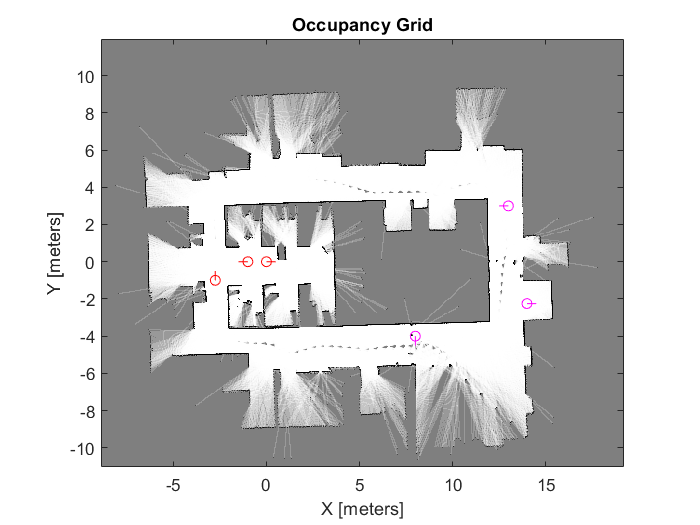

% Show start and goal positions of robot.
hold on
% for agent A
plot(Astart(1),Astart(2),'ro')
plot(Agoal(1),Agoal(2),'mo')

% for agent B
plot(Bstart(1),Bstart(2),'ro')
plot(Bgoal(1),Bgoal(2),'mo')

% for agent C
plot(Cstart(1),Cstart(2),'ro')
plot(Cgoal(1),Cgoal(2),'mo')

% Show start and goal heading for agent A
r = 0.5;
plot([Astart(1),Astart(1) + r*cos(Astart(3))],[Astart(2),Astart(2) + r*sin(Astart(3))],'r-')
plot([Agoal(1),Agoal(1) + r*cos(Agoal(3))],[Agoal(2),Agoal(2) + r*sin(Agoal(3))],'m-')

% Show start and goal heading for agent B

plot([Bstart(1),Bstart(1) + r*cos(Bstart(3))],[Bstart(2),Bstart(2) + r*sin(Bstart(3))],'r-')
plot([Bgoal(1),Bgoal(1) + r*cos(Bgoal(3))],[Bgoal(2),Bgoal(2) + r*sin(Bgoal(3))],'m-')

% Show start and goal heading for agent C
plot([Cstart(1),Cstart(1) + r*cos(Cstart(3))],[Cstart(2),Cstart(2) + r*sin(Cstart(3))],'r-')
plot([Cgoal(1),Cgoal(1) + r*cos(Cgoal(3))],[Cgoal(2),Cgoal(2) + r*sin(Cgoal(3))],'m-')

hold off

## Define State Space

Specify the state space of the vehicle using a `stateSpaceDubins` object and specifying the state bounds. This object limits the sampled states to feasible Dubins curves for steering a vehicle within the state bounds. A turning radius of 0.4 meters allows for tight turns in this small environment.

bounds = [occGrid.XWorldLimits; occGrid.YWorldLimits; [-pi pi]];

ss = stateSpaceDubins(bounds);
ss.MinTurningRadius = 0.4;

## Plan The Path

To plan a path, the RRT algorithm samples random states within the state space and attempts to connect a path. These states and connections need to be validated or excluded based on the map constraints. The vehicle must not collide with obstacles defined in the map.

Create a `validatorOccupancyMap` object with the specified state space. Set the `Map` property to the loaded `occupancyMap` object. Set a `ValdiationDistance` of 0.05 m. This validation distance discretizes the path connections and checks obstacles in the map based on this.  

stateValidator = validatorOccupancyMap(ss); 
stateValidator.Map = occGrid;
stateValidator.ValidationDistance = 0.05;

Create the path planner and increase the max connection distance to connect more states. Set the maximum number of iterations for sampling states.

planner = plannerRRT(ss,stateValidator);
planner.MaxConnectionDistance = 1;
planner.MaxIterations = 30000;

Customize the `GoalReached` function. This example helper function checks if a feasible path reaches the goal within a set threshold. The function returns `true` when the goal has been reached, and the planner stops.

planner.GoalReachedFcn = @exampleHelperCheckIfGoal;

Plan the path between the start and goal. Reset the random number generator for reproducible results. 

rng default

% planning initially for agent A
[pthObjA, solnInfoA] = plan(planner,Astart,Agoal);

% save all the nodes in a array for agent A
NodesA=pthObjA.States;

% x=NodesA(1,2);

% planning initially for agent B
[pthObjB, solnInfoB] = plan(planner,Bstart,Bgoal);

% save all the nodes in a array for agent B
NodesB=pthObjB.States;

% planning initially for agent C
[pthObjC, solnInfoC] = plan(planner,Cstart,Cgoal);

% save all the nodes in an array for agent C
NodesC = pthObjC.States;




A pahunch gya, B update karo
A pahunch gya, B update karo
A pahunch gya, B update karo
A pahunch gya, B update karo
A pahunch gya, B update karo
A pahunch gya, B update karo
A pahunch gya, B update karo
A pahunch gya, B update karo
A pahunch gya, B update karo
A pahunch gya, B update karo
A pahunch gya, B update karo
A pahunch gya, B update karo
A pahunch gya, B update karo
A pahunch gya, B update karo


B pahunch gya, C update karo
B pahunch gya, C update karo


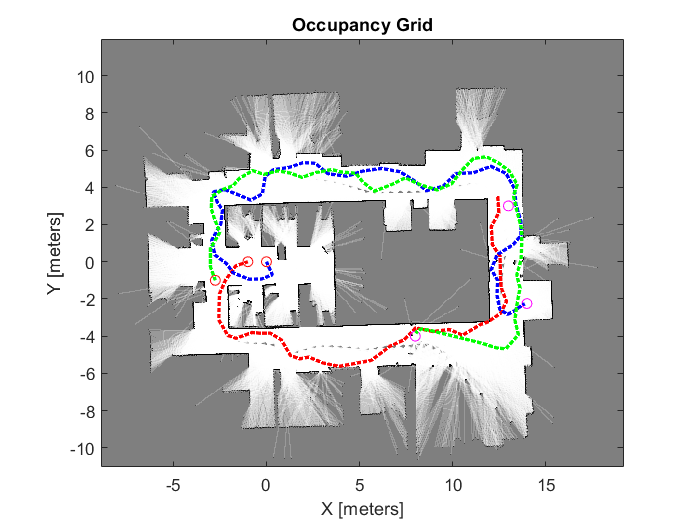

% now implementing rrt between two consecutive nodes using a loop

% Initialize arrays to store states
allStatesA = [];
allStatesB = [];
allStatesC = [];

allNodes = [numel(NodesA(:,1)),numel(NodesB(:,1)),numel(NodesC(:,1))];
nodescount = max(allNodes);
% nodescount= numel(NodesA(:,1)); % finding the total number of nodes in the final path, now its same, but would take the smaller one

for n=1:nodescount-1
statusA = 0;
statusB = 0;
statusC = 0;

if (n>=allNodes(1) && n<allNodes(2))
    disp("A pahunch gya, B update karo")
    if(sqrt((NodesB(n,1) - NodesA(allNodes(1),1))^2 + (NodesB(n,2) - NodesA(allNodes(1),2))^2) < 0.5)
%%%%%%%%%%%%%%%%%%%% updating the paths %%%%%%%%%%%%%%%%%%%%
        
        statusA=1;
        statusB=0;
    
    %     [finalpathC, solutionC] = individualPlanner(n,NodesC);
    %     finalpathC() = pthObjC;
    %     solutionC = solnInfoC;
        [finalpathB, solutionB]= interplanner(n,NodesA,NodesB,statusA,statusB);
        allStatesB = [allStatesB;finalpathB.States(:,:)];
    end
   

    
elseif(n<allNodes(1) && n>=allNodes(2))
    disp("B pahunch gya, A update karo")
    if(sqrt((NodesB(allNodes(2),1) - NodesA(n,1))^2 + (NodesB(allNodes(1),2) - NodesA(n,2))^2) < 0.5)
%%%%%%%%%%%%%%%%%%%% updating the paths %%%%%%%%%%%%%%%%%%%%
        
        statusA=0;
        statusB=1;
    
    %     [finalpathC, solutionC] = individualPlanner(n,NodesC);
    %     finalpathC() = pthObjC;
    %     solutionC = solnInfoC;
        [finalpathA, solutionA]= interplanner(n,NodesA,NodesB,statusA,statusB);
        allStatesA = [allStatesA;finalpathA.States(:,:)];
    end
    



elseif(n>=allNodes(2) && n<allNodes(3)) 
    disp("B pahunch gya, C update karo")
    if (sqrt((NodesB(allNodes(2),1) - NodesC(n,1))^2 + (NodesB(allNodes(2),2) - NodesC(n,2))^2) < 0.5)
        
        statusC = 0;
        statusB = 1;
        
    %      [finalpathA, solutionA] = individualPlanner(n,NodesA);
    %     finalpathA = pthObjA;
    %     solutionA = solnInfoA;
        [finalpathC, solutionC]= interplanner(n,NodesB,NodesC,statusC,statusB);
        allStatesC = [allStatesC;finalpathC.States(:,:)];
       
    end

elseif(n<allNodes(2) && n>=allNodes(3)) 
    disp("C pahunch gya, B update karo")
    if (sqrt((NodesB(n,1) - NodesC(allNodes(3),1))^2 + (NodesB(n,2) - NodesC(allNodes(3),2))^2) < 0.5)
        
        statusC = 1;
        statusB = 0;
        
    %      [finalpathA, solutionA] = individualPlanner(n,NodesA);
    %     finalpathA = pthObjA;
    %     solutionA = solnInfoA;
        [finalpathB, solutionB]= interplanner(n,NodesB,NodesC,statusC,statusB);
        allStatesB = [allStatesB;finalpathB.States(:,:)];
    end

elseif(n>=allNodes(3)  && n<allNodes(1))
    disp("C pahunch gya, A update karo")
    if (sqrt((NodesA(n,1) - NodesC(allNodes(3),1))^2 + (NodesA(n,2) - NodesC(allNodes(3),2))^2) < 0.5)
        
        statusC = 1;
        statusA = 0;
    
%     [finalpathB, solutionB] = individualPlanner(n,NodesB);
%     finalpathB = pthObjB;
%     solutionB = solnInfoB;
        [finalpathA, solutionA]= interplanner(n,NodesA,NodesC,statusC,statusA); 
        allStatesA = [allStatesA;finalpathA.States(:,:)];
    end  
 
elseif(n<allNodes(3)  && n>=allNodes(1))
    disp("A pahunch gya, B update karo")
    if (sqrt((NodesA(allNodes(1),1) - NodesC(n,1))^2 + (NodesA(allNodes(1),2) - NodesC(n,2))^2) < 0.5)
        
        statusC = 0;
        statusA = 1;
        
    %     [finalpathB, solutionB] = individualPlanner(n,NodesB);
    %     finalpathB = pthObjB;
    %     solutionB = solnInfoB;
        [finalpathC, solutionC]= interplanner(n,NodesA,NodesC,statusC,statusA);
        allStatesC = [allStatesC;finalpathC.States(:,:)];
    
    end    
    
else
    
    if(sqrt((NodesA(n,1) - NodesC(n,1))^2 + (NodesA(n,2) - NodesC(n,2))^2) < 1)
        disp("A and C ka distance is less than 0.5")
        statusA = 1;
        statusC = 0;
        
        [finalpathC, solutionC] = interplanner(n,NodesA,NodesC,statusC,statusA);
        allStatesC = [allStatesC;finalpathC.States(:,:)];
        
    
    elseif(sqrt((NodesB(n,1) - NodesC(n,1))^2 + (NodesB(n,2) - NodesC(n,2))^2) < 1)
        disp("C and B ka distance is less than 0.5")
        statusB = 1;
        statusC = 0;
        
        [finalpathC, solutionC] = interplanner(n,NodesB,NodesC,statusC,statusB);
        allStatesC = [allStatesC;finalpathC.States(:,:)];
       
    elseif(sqrt((NodesA(n,1) - NodesB(n,1))^2 + (NodesA(n,2) - NodesB(n,2))^2) < 1)
        disp("A and B ka distance is less than 0.5")
        statusB = 0;
        statusA = 1;
        
        [finalpathB, solutionB] = interplanner(n, NodesA, NodesB, statusA, statusB);
         allStatesB = [allStatesB;finalpathB.States(:,:)];
    else
%         disp(finalpathA.States(n,:))
%         disp(finalpathB.States(n,:))
%         disp(finalpathC.States(n,:))
%         if(isempty(evalin('base','who("finalpathA")')))
%             allStatesA = [allStatesA;pthObjA.States(n,:)];
%         else
%             allStatesA = [allStatesA; finalpathA.States];
%         end
%         if(isempty(evalin('base','who("finalpathB")')))
%             allStatesB = [allStatesB;pthObjB.States(n,:)];
%         else
%             allStatesB = [allStatesB;finalpathB.States];
%         end  
%         if(isempty(evalin('base','who("finalpathC")')))
%             allStatesC = [allStatesC;pthObjC.States(n,:)];
%         else
%             allStatesC = [allStatesB;finalpathC.States];
%         end   
          
         
    end
        

end
    
% statusA=0;
% statusB=1;
% 
% [finalpathA, solutionA]= interplanner(n,NodesA,NodesB,statusA,statusB);

%%%%%%%%%%%%%%%%%%%% updating the paths %%%%%%%%%%%%%%%%%%%%
% [finalpathA, solutionA] = individualPlanner(n,NodesA);
% [finalpathB, solutionB] = individualPlanner(n,NodesB);





%%%%%%%%% animating the paths %%%%%%%%%

% Store the states for plotting
% if(isempty(evalin('base','who("finalpathA")')))
if(n<allNodes(1))
    allStatesA = [allStatesA;pthObjA.States(n,:)];
end
% else
%     allStatesA = [allStatesA; finalpathA.States(n,:)];
% end
% if(isempty(evalin('base','who("finalpathB")')))
if(n<allNodes(2))
    allStatesB = [allStatesB;pthObjB.States(n,:)];
end
% else
%     allStatesB = [allStatesB;finalpathB.States(n,:)];
% end
% if(isempty(evalin('base','who("finalpathC")')))
if(n<allNodes(3))
    allStatesC = [allStatesC;pthObjC.States(n,:)];
end
% else
%     allStatesC = [allStatesB;finalpathC.States(n,:)];
% end

% Clear the current figure
% clf;

% Show the occupancy grid
show(occGrid);
hold on;

% Show start and goal in grid map for pthObjA
plot(Astart(1),Astart(2),'ro');
plot(Agoal(1),Agoal(2),'mo');

plot(allStatesA(:,1), allStatesA(:,2), 'r-', 'LineWidth', 2, 'LineStyle', ':');
if n<allNodes(1)
%     disp("A ka path plot hora")
    
     if(isempty(evalin('base','who("finalpathA")')))
%             
     else
            plot(finalpathA.States(:,1),finalpathA.States(:,2),'r-','LineWidth',2);
     end
    
end

% Show start and goal in grid map for pthObjB
plot(Bstart(1),Bstart(2),'ro');
plot(Bgoal(1),Bgoal(2),'mo');

plot(allStatesB(:,1), allStatesB(:,2), 'b-', 'LineWidth', 2, 'LineStyle', ':');
if n<allNodes(2)
%     disp("B ka path plot hora")
    
     if(isempty(evalin('base','who("finalpathB")')))
%             
     else
           plot(finalpathB.States(:,1),finalpathB.States(:,2),'b-','LineWidth',2);
     end
    
end

% Show start and goal in grid map for pthObjB
plot(Cstart(1),Cstart(2),'ro');
plot(Cgoal(1),Cgoal(2),'mo');

plot(allStatesC(:,1), allStatesC(:,2), 'g-', 'LineWidth', 2, 'LineStyle', ':');
if n<allNodes(3)
%     disp("C ka path plot hora")
    
   
    if(isempty(evalin('base','who("finalpathB")')))
%             
     else
           plot(finalpathC.States(:,1),finalpathC.States(:,2),'g-','LineWidth',2);
     end
    

   
end



hold off 


% Pause for a short duration to allow figure to update
pause(1); % Adjust the duration as needed

end

% plotting the path simultaneously for both the agents
% creating a function in which I will send the points for the agents. 


## Plot the Path

Show the occupancy map. Plot the search tree from the `solnInfo`. Interpolate and overlay the final path.

% show(occGrid)
% hold on
% 
% % Plot entire search tree.
% plot(solnInfoA.TreeData(:,1),solnInfoA.TreeData(:,2),'.-');
% 
% % Interpolate and plot path.
% interpolate(pthObjA,300)
% plot(pthObjA.States(:,1),pthObjA.States(:,2),'r-','LineWidth',2)
% 
% % Show start and goal in grid map.
% plot(Astart(1),Astart(2),'ro')
% plot(Agoal(1),Agoal(2),'mo')
% 
% 
% 
% % Plot entire search tree.
% plot(solnInfoB.TreeData(:,1),solnInfoB.TreeData(:,2),'.-');
% 
% % Interpolate and plot path.
% interpolate(pthObjB,300)
% plot(pthObjB.States(:,1),pthObjB.States(:,2),'b-','LineWidth',2)
% 
% % Show start and goal in grid map.
% plot(Bstart(1),Bstart(2),'ro')
% plot(Bgoal(1),Bgoal(2),'mo')
% 
% 
% hold off

## Customize Dubins Vehicle Constraints

To specify custom vehicle constraints, customize the state space object. This example uses `ExampleHelperStateSpaceOneSidedDubins`, which is based on the `stateSpaceDubins` class. This helper class limits the turning direction to either right or left based on a Boolean property, `GoLeft`. This property essentially disables path types of the `dubinsConnection` object.

Create the state space object using the example helper. Specify the same state bounds and give the new Boolean parameter as `true` (left turns only).

% % Only making left turns
% goLeft = true;
% 
% % Create the state space
% ssCustom = ExampleHelperStateSpaceOneSidedDubins(bounds,goLeft);
% ssCustom.MinTurningRadius = 0.4;

## Plan Path

Create a new planner object with the custom Dubins constraints and a validator based on those constraints. Specify the same `GoalReached` function.

% stateValidator2 = validatorOccupancyMap(ssCustom); 
% stateValidator2.Map = occGrid;
% stateValidator2.ValidationDistance = 0.05;
% 
% planner = plannerRRT(ssCustom,stateValidator2);
% planner.MaxConnectionDistance = 2.0;
% planner.MaxIterations = 30000;
% planner.GoalReachedFcn = @exampleHelperCheckIfGoal;

Plan the path between the start and goal. Reset the random number generator again.

% rng default
% [pthObj2,solnInfo] = plan(planner,start,goal);

## Plot Path

Draw the new path on the map. The path should only execute left turns to reach the goal.

% figure
% show(occGrid)
% 
% hold on
% 
% % Show the search tree.
% plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2),'.-');
% 
% % Interpolate and plot path.
% pthObj2.interpolate(300)
% plot(pthObj2.States(:,1), pthObj2.States(:,2), 'r-', 'LineWidth', 2)
% 
% % Show start and goal in grid map.
% plot(start(1), start(2), 'ro')
% plot(goal(1), goal(2), 'mo')
% hold off




*Copyright 2019 The MathWorks, Inc.*